syms t 

k=11104.588

k = 1.1105e+04

c=1429.42

c = 1.4294e+03

ode= 46*diff(y,2)+c*diff(y)+k*y ==-450.8;
%yf = (450.8/k)*exp((-sqrt(k/46))*t)+(-5.42+9.8*sqrt(46/k))*t*exp((-sqrt(k/46))*t)-(450.8/k);
dy=diff(y);
cond1= y(0)==0;
cond2=dy(0)== -5.42;
conds=[cond1,cond2];
ysol(t)= dsolve(ode,conds)

$$ysol(t) = \frac{619574802251776\,{\mathrm{e}}^{-\frac{71471\,t}{4600}}\,\cos\left(\frac{\sqrt{114057151510506}\,t}{602931200}\right)}{15262029534577295}-\frac{22035253799442476986793984\,\sqrt{114057151510506}\,{\mathrm{e}}^{-\frac{71471\,t}{4600}}\,\sin\left(\frac{\sqrt{114057151510506}\,t}{602931200}\right)}{870371807491549953282730780635}-\frac{619574802251776}{15262029534577295}$$

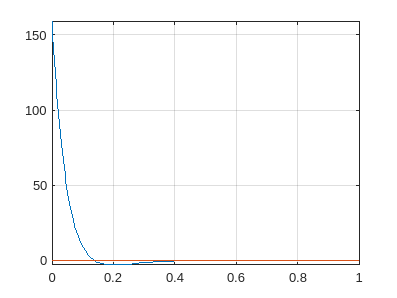

%ysol=simplify(ysol)
d2y=diff(ysol,t);
d2y=diff(d2y,t);
%ysol=simplify(d2y)
fplot(d2y,[0,1])
hold on
fplot(ysol,[0,1])
grid
hold off